**Exercise 1: Quadrature of a Parabola**

Trying it out again

a = 1

a = 1

r = 1/4

r = 0.2500

area_analytical = 4/3

area_analytical = 1.3333


% create a vector with elements 1 to 20
range = 1:20

range =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


element = (1/4).^(range-1)

element =     1.0000    0.2500    0.0625    0.0156    0.0039    0.0010    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


p_sums = cumsum(element)

p_sums =     1.0000    1.2500    1.3125    1.3281    1.3320    1.3330    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333


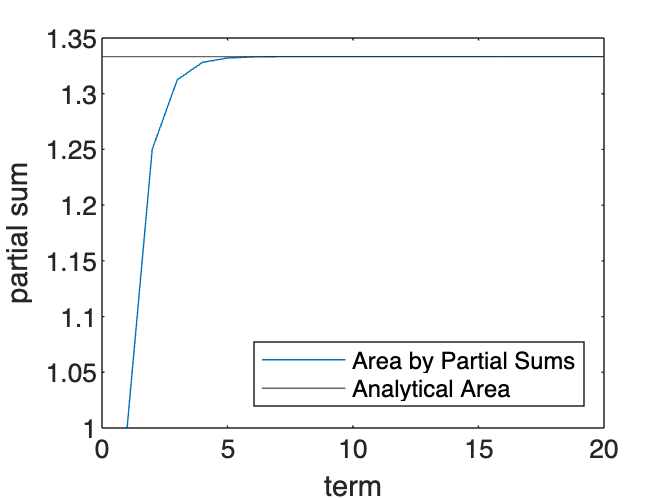


plot(range, p_sums)
hold on
yline(area_analytical)
hold off
xlabel("term")
ylabel("partial sum")
legend("Area by Partial Sums", "Analytical Area", "Location", "southeast")

**Exercise 2: Numerical Integration**

soln_analytical = 14/3

soln_analytical = 4.6667

a = 0

a = 0

b = 3

b = 3

%n = 10

Ln = zeros(100-10+1, 1)

Ln =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Rn = zeros(100-10+1, 1)

Rn =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


n = 10:100

n =     10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59


dx = (b-a)./n

dx =     0.3000    0.2727    0.2500    0.2308    0.2143    0.2000    0.1875    0.1765    0.1667    0.1579    0.1500    0.1429    0.1364    0.1304    0.1250    0.1200    0.1154    0.1111    0.1071    0.1034    0.1000    0.0968    0.0938    0.0909    0.0882    0.0857    0.0833    0.0811    0.0789    0.0769    0.0750    0.0732    0.0714    0.0698    0.0682    0.0667    0.0652    0.0638    0.0625    0.0612    0.0600    0.0588    0.0577    0.0566    0.0556    0.0545    0.0536    0.0526    0.0517    0.0508


for i = n-9
    
    % left
    x_l = a:dx(i):b-dx(i);
    fxl = sqrt(x_l+1);
    eL = dx(i) .* fxl;
    sumL_all = cumsum(eL);
    Ln(i) = sumL_all(end);
    
    % right
    x_r = a+dx(i):dx(i):b;
    fxr = sqrt(x_r+1);
    eR = dx(i) .* fxr;
    sumR_all = cumsum(eR);
    Rn(i) = sumR_all(end);
end

soln_analytical

soln_analytical = 4.6667

Ln

Ln =     4.5148
    4.5288
    4.5404
    4.5502
    4.5586
    4.5658
    4.5722
    4.5778
    4.5828
    4.5872


Rn

Rn =     4.8148
    4.8015
    4.7904
    4.7809
    4.7729
    4.7658
    4.7597
    4.7543
    4.7494
    4.7451


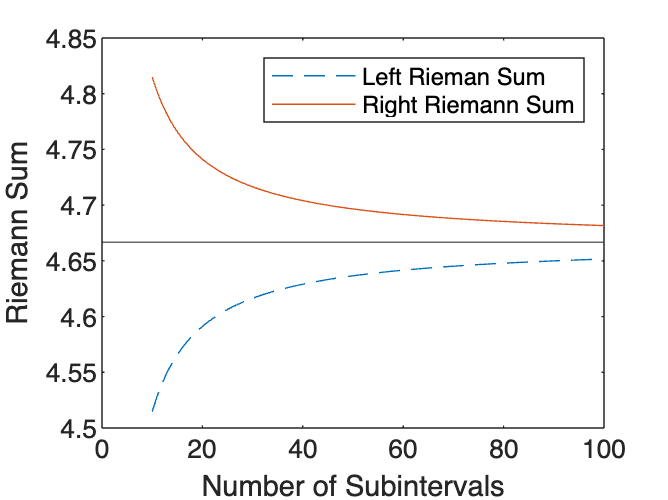

plot(n, Ln, "--")
hold on
plot(n, Rn)
yline(soln_analytical)
xlabel("Number of Subintervals")
ylabel("Riemann Sum")
legend("Left Rieman Sum", "Right Riemann Sum")